# Calcolo Numerico con Laboratorio 

# Compito a casa 

# 25 ottobre 2021

## Esercizio 1

La figura rappresenta un traliccio con 13 elementi (le linee numerate) che connettono 8 giunti (i cerchi numerati). I pesi indicati, in tonnellate, sono applicate ai giunti 2, 5 e 6.

Vogliamo determinare le forze risultanti su ciascun elemento della travatura.

Affinche' la travatura sia in equilibrio statico le forze si devono compensare sia orizzontalmente che verticalmente. Quindi possiamo determinare le forze di ciascun elemento uguagliando le forze orizzontali alla sinistra e alla destra di ciascun giunto e quelle verticali sopra e sotto. Avendo 8 giunti otteniamo 16 equazioni che sono di piu' delle incognite. Aggiungiamo quindi la condizione che il giunto 1 sia fissato rigidamente e verticalmente e che il giunto 8 sia fissato verticalmente.

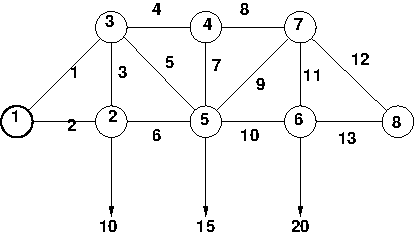

Posto $\alpha=1/\sqrt{2}$, otteniamo il seguente sistema di equazioni:


$$\begin{array}{ll}
\text{Giunto 2}:&&f_2=f_6\\
&&f_3=10;
\end{array}

$$



$$\begin{array}{ll}
\text{Giunto 3}:
&&\alpha f_1=f_4+\alpha f_5\\
&&\alpha f_1+f_3+\alpha f_5=0;
\end{array}

$$



$$\begin{array}{ll}
\text{Giunto 4}:&&f_4=f_8\\
&&f_7=0;
\end{array}

$$



$$\begin{array}{ll}
\text{Giunto 5}:&&
\alpha f_5+f_6=\alpha f_9+f_{10}\\
&&\alpha f_5+f_7+\alpha f_9=15;
\end{array}

$$



$$\begin{array}{ll}
\text{Giunto 6}:&&f_{10}=f_{13}\\
&&f_{11}=20;
\end{array}

$$



$$\begin{array}{ll}
\text{Giunto 7}:&&
f_8+\alpha f_9=\alpha f_{12}\\
&&\alpha f_9+f_{11}+\alpha f_{12}=0;
\end{array}

$$



$$
\text{Giunto 8}:\quad \alpha f_{12}+f_{13}=0\\

$$


Scrivere la matrice e il termine noto  del sistema lineare.

Risolvere il sistema lineare.

Calcolare il numero di condizionamento della matrice e il residuo.

a=1/sqrt(2);
A=[0 1 0 0 0 -1 0 0 0 0 0 0 0;
    0 0 1 0 0 0 0 0 0 0 0 0 0;
    a 0 0 -1 -a 0 0 0 0 0 0 0 0;
    a 0 1 0 a 0 0 0 0 0 0 0 0;
    0 0 0 1 0 0 0 -1 0 0 0 0 0;
    0 0 0 0 0 0 1 0 0 0 0 0 0;
    0 0 0 0 a 1 0 0 -a -1 0 0 0;
    0 0 0 0 a 0 1 0 a 0 0 0 0;
    0 0 0 0 0 0 0 0 0 1 0 0 -1;
    0 0 0 0 0 0 0 0 0 0 1 0 0;
    0 0 0 0 0 0 0 1 a 0 0 -a 0;
    0 0 0 0 0 0 0 0 a 0 1 a 0;
    0 0 0 0 0 0 0 0 0 0 0 a 1];
B=[0 10 0 0 0 0 0 15 0 20 0 0 0];
f=A\B'

f =   -28.2843
   20.0000
   10.0000
  -30.0000
   14.1421
   20.0000
         0
  -30.0000
    7.0711
   25.0000


K=cond(A)

K = 10.4122

residuo=norm(A*f-B)

residuo = 86.0233

## Esercizio 2

Al variare di `n=50:50:500`, si consideri il sistema lineare $Ax=b$ con $A\in\mathbb{R}^{n\times n}$ matrice tridiagonale con i seguenti elementi:

$a_{ii}=2,\quad a_{ii-1}=a_{ii+1}=-1,$ e $b=(1,-1,1,\dots,(-1)^{n-1})^T$.

Per ciascun valore di `n`:

- calcolare la soluzione $x$ di tale sistema;

- introdurre una perturbazione al termino noto $r=10^{-8}*(1,1,\cdots,1)^T$ e calcolare la soluzione del sistema perturbato $A\hat x=b+r$;

- calcolare l'errore relativo $\|x-\hat x\|/\|x\|$, il residuo relativo $\|r\|/\|b\|$, il numero di condizionamento della matrice $A$ (`cond(A)`), la stima teorica dell'errore (cond(A) $\|r\|/\|b\|$) .

Riportare in un grafico in scala bilogaritmica (`loglog`) al variare di `n` il numero di condizionamento della matrice, l'errore relativo, il residuo e la stima teorica.

Osservato che il grafico in scala bilogaritmica del numero di condizionamento è lineare, si può dare una espressione all'andamento del numero di condizionamento in funzione di `n`?

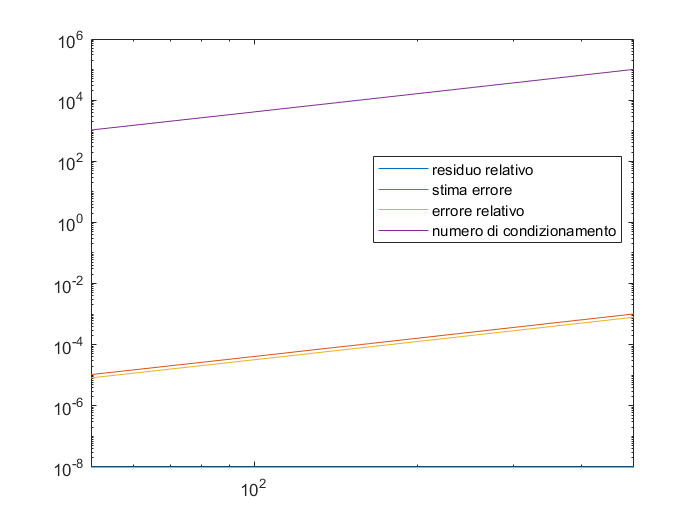

clear all 
close all
e=[];
k=[];
R=[];
se=[];
for n=50:50:500
    A=eye(n)*2;
    V(1:n-1)=-1;
%     A(2:n+1:n*n)=-1;
%     A(n+1:n+1:n*n)=-1;
    A=A+diag(V,1)+diag(V,-1);
    B(1:2:n)=1;
    B(2:2:n)=-1;
    X=A\B';
    r=ones(1,n)*10^-8;
    R=[R norm(r)/norm(B)];  %residuo relativo
    Xc=A\(B+r)';
    k=[k cond(A)];  %numero di condizionamento
    e=[e norm(X-Xc)/norm(X)];   %errore relativo
    se=[se cond(A)*norm(r)/norm(B)]; %stima errore relativo
end
loglog(50:50:500,R)
hold on
loglog(50:50:500,se)
loglog(50:50:500,e)
loglog(50:50:500,k)
legend("residuo relativo","stima errore","errore relativo","numero di condizionamento","Location","best")

il numero di condizionamento ha un andamento quadratico al crescere di n.

## Esercizio 3 - 

#### Function `bisezione `*(facoltativo)*

Scrivere una function per trovare uno zero di una funzione con il metodo delle bisezioni:

`function [zero,fval,iter]=bisezione(f,a,b,tol)`

### Input

`f` nome della funzione

`a,b`  estremi dell'intervallo

`tol `tolleranza desiderata.

### Output

`zero` lo zero della funzione trovato

`fval` valore di f nello zero calcolato

`iter` iterazioni eseguite.

Testare la function per trovare uno zero delle seguenti funzioni con tolleranza `tol=eps.`

$f(x)=x^2-2$`, `$x\in[0,2]$

$f(x)=3x-1$`, `$x\in[0,1]$

$f(x)=\arctan(x)$`, `$x\in[-1,1]$

$f(x)=\sin(x)-\cos(2x)$`, `$x\in[-\pi,\pi]$ tenendo conto della periodicità della funzione scegliere opportunamente l'intervallo

Fare il grafico della funzione insieme all'asse x e riportare lo zero trovato.

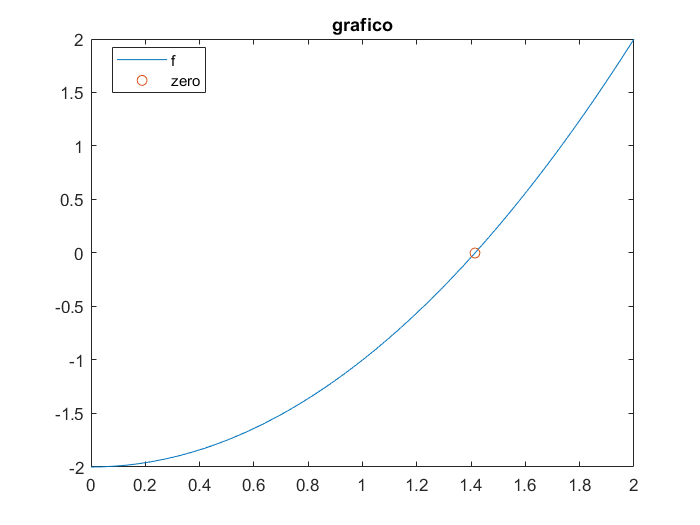

clear all
close all
f=@(x) x.^2-2;
a=0;b=2;
[x,y,iter,flag]=bisezione(f,a,b,eps,100);
fplot(f,[a b])
hold on 
plotSave({x},{y},"grafico",["f","zero"],"o")

clear all
close all
f=@(x) sin(x)-cos(2*x);
a=-pi;b=pi;
[x,y,iter,flag]=bisezione(f,0,1,eps,100);
[x1,y1,iter,flag]=bisezione(f,2,3,eps,100);
fplot(f,[a b])
hold on 
assex=@(x) 0;
fplot(assex,[a b])

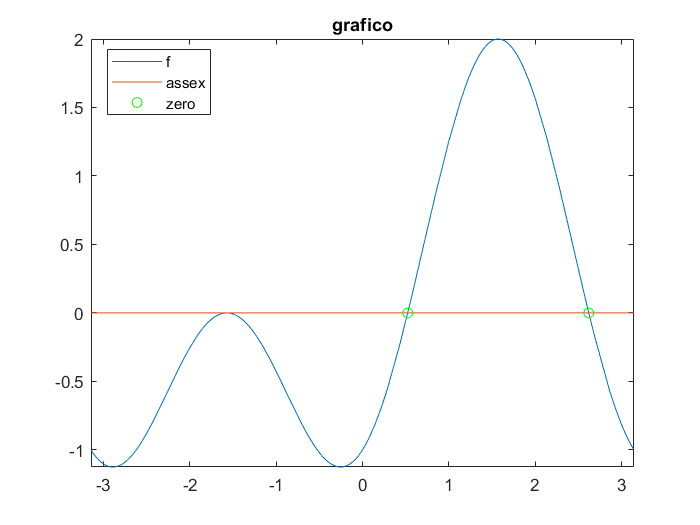

plotSave({x,x1},{y,y1},"grafico",["f","assex","zero"],["og","og"])